# Custom Symbol Mapping of 16-PSK

Create 16-PSK modulator and demodulator System objects™ that use custom symbol mapping. Estimate the BER in an AWGN channel and compare the performance to a theoretical Gray-coded PSK system.

Create a custom symbol mapping for the 16-PSK modulation scheme. The 16 integer symbols must have values in the range [0, 15].

custMap = [0 2 4 6 8 10 12 14 15 13 11 9 7 5 3 1];

Create a 16-PSK modulator and demodulator pair having custom symbol mapping defined by the array `custMap`.

pskModulator = comm.PSKModulator(16,'BitInput',true, ...
    'SymbolMapping','Custom','CustomSymbolMapping',custMap);
pskDemodulator = comm.PSKDemodulator(16,'BitOutput',true, ...
    'SymbolMapping','Custom','CustomSymbolMapping',custMap);

Display the modulator constellation.

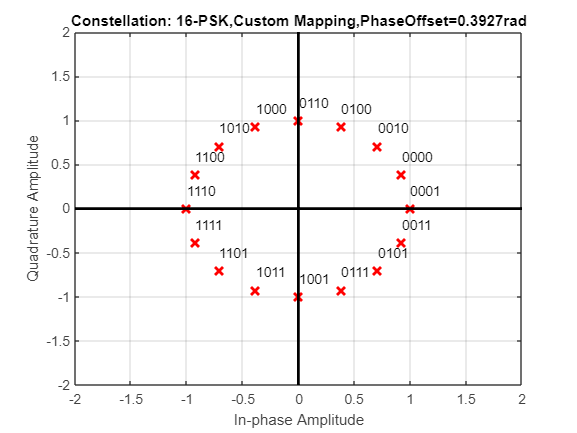

constellation(pskModulator)

Create an AWGN channel System object for use with 16-ary data.

awgnChannel = comm.AWGNChannel('BitsPerSymbol',log2(16));

Create an error rate object to track the BER statistics.

errorRate = comm.ErrorRate;

Initialize the simulation vectors. Vary $E_{\mathrm{b}} /N_0$ from 6 to 18 dB in 1 dB steps.

ebnoVec = 6:18;
ber = zeros(size(ebnoVec));

Estimate the BER by modulating binary data, passing it through an AWGN channel, demodulating the received signal, and collecting the error statistics.

for n = 1:length(ebnoVec)
    
    % Reset the error counter for each Eb/No value
    reset(errorRate)
    % Reset the array used to collect the error statistics
    errVec = [0 0 0];
    % Set the channel Eb/No
    awgnChannel.EbNo = ebnoVec(n);
    
    while errVec(2) < 200 && errVec(3) < 1e7
        % Generate a 1000-symbol frame
        data = randi([0 1],4000,1);
        % Modulate the binary data
        modData = pskModulator(data);
        % Pass the modulated data through the AWGN channel
        rxSig = awgnChannel(modData);
        % Demodulate the received signal
        rxData = pskDemodulator(rxSig);
        % Collect the error statistics
        errVec = errorRate(data,rxData);
    end
    
    % Save the BER data
    ber(n) = errVec(1);
end

Generate theoretical BER data for an AWGN channel using the [berawgn](docid:comm_ref#fp1562672) function.

berTheory = berawgn(ebnoVec,'psk',16,'nondiff');

Plot the simulated and theoretical results. The 16-PSK modulation BER performance of the simulated custom symbol mapping is not as good as the theoretical prediction curve for Gray codes.

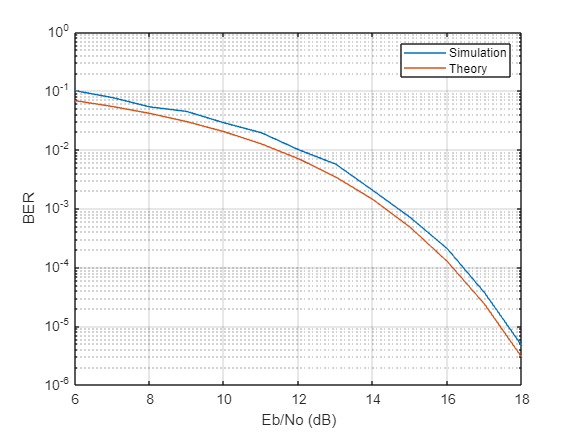

figure
semilogy(ebnoVec,[ber; berTheory])
xlabel('Eb/No (dB)')
ylabel('BER')
grid
legend('Simulation','Theory','location','ne')

*Copyright 2012 The MathWorks, Inc.*